
% 参数设置
N = 81; K = 50;
% N = 64; K = 37;
% N = 225; K = 128;
Lx = 1; Ly = 1; % 计算区域边长
R = 0; % 点的最小间距
M = 0;
D = 0;
alpha = 0;

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     129    2.452131e-01    0.000e+00    2.650e+00
    1     269    2.211108e-01    0.000e+00    3.341e+00    2.569e-03
    2     400    2.123449e-01    0.000e+00    8.867e+00    4.420e-03
    3     533    2.075037e-01    0.000e+00    4.901e+00    4.505e-03


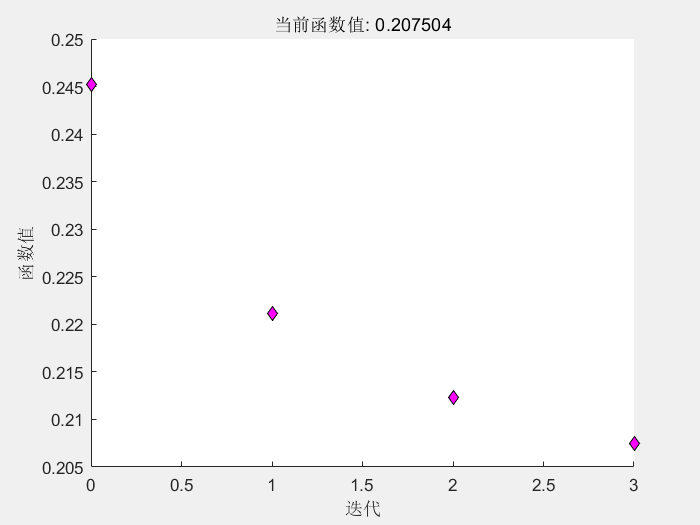


fmincon stopped by the output or plot function.




% 生成 Hyperuniform 点分布
% K是截止波数的平方
% start_points = hyperuniform_points;
start_points = rand(N, 2) .* [Lx, Ly];
hyperuniform_points = generate_hyperuniform_points(start_points, N, Lx, Ly, K, R, D, alpha);

hyperuniform_points = reshape(hyperuniform_points, N, 2);

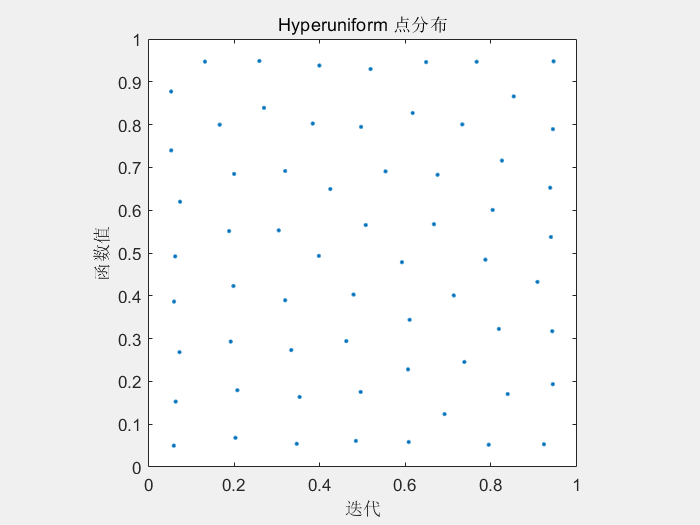

% 绘制点分布
figure (1);
p = scatter(hyperuniform_points(:, 1), hyperuniform_points(:, 2), 50, '.');
axis equal;  
xlim([0, Lx]);
ylim([0, Ly]);
title('Hyperuniform 点分布'); 
box on;

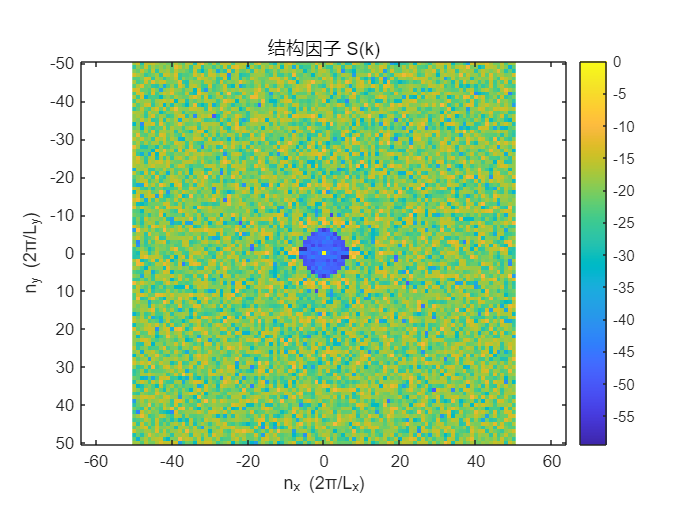


% 定义倒空间波矢范围
k_max = 50;         % 最大波矢值（单位：2π/L）
k_resolution = 101; % 分辨率
[kx, ky] = meshgrid(linspace(-k_max, k_max, k_resolution), ...
                    linspace(-k_max, k_max, k_resolution));

% 计算结构因子 S(k)
S = zeros(size(kx));
Mk = 0;
for i = 1:numel(kx)
    k = 2 * pi * [kx(i)/Lx, ky(i)/Ly];  % 波矢定义（实际物理单位）
    if kx(i) ^2 + ky(i) ^2 <= K
        Mk = Mk+1;
    end
    sum_exp = 0;
    for j = 1:N
        sum_exp = sum_exp + exp(1j * dot(k, hyperuniform_points(j, :)));
    end
    S(i) = abs(sum_exp)^2 / N;
end

Mk = (Mk-1)/2;
chi = Mk /2 /N;
norm_S = 10 * log10(S / max(S(:)));
% 绘制结构因子
figure (2);
imagesc(kx(1,:), ky(:,1), norm_S); % 对数刻度，避免 log(0)
axis equal;
xlabel('n_x (2π/L_x)');
ylabel('n_y (2π/L_y)');
title('结构因子 S(k)');
colorbar;

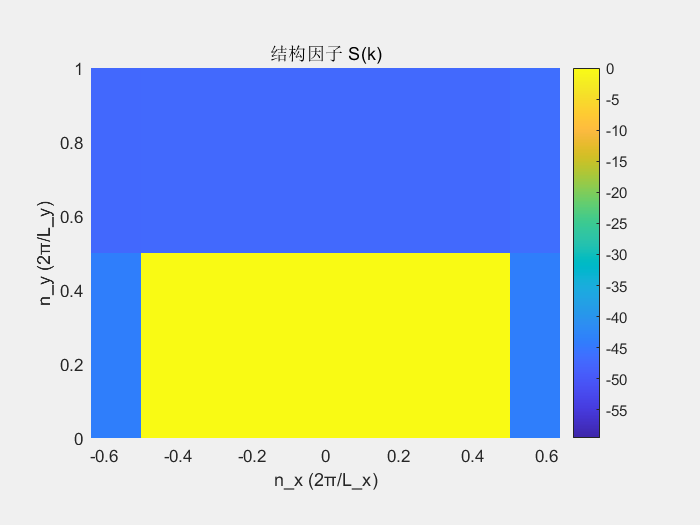

% 叠加截止区域圆（K）
hold on;
theta = 0:0.01:2*pi;
x_circle = sqrt(K) * cos(theta);
y_circle = sqrt(K) * sin(theta);
plot(x_circle, y_circle, 'r--', 'LineWidth', 1);
hold off;

function hyperuniform_points = generate_hyperuniform_points(start_points, N, Lx, Ly, K, R, D, alpha)
    % 生成 Hyperuniform 点分布
    % 输入参数：
    %   N: 点的数量
    %   Lx, Ly: 计算区域的边长
    %   K: 倒空间截止波数
    %   R: 点的最小间距（硬球半径）
    % 输出：
    %   hyperuniform_points: N x 2 矩阵，表示点的坐标

    % 初始化随机点分布
    points = start_points;

    % 定义优化目标函数
    objective = @(x) total_potential_energy(x, N, Lx, Ly, K, D, alpha);

    % 定义约束条件
    nonlcon = @(x) constraints(x, N, R, Lx, Ly);

    % 示例：使用遗传算法
%     options_ga = optimoptions('ga', 'PopulationSize', 100, 'MaxGenerations', 100, 'Display','iter', 'UseParallel', true);
%     optimized_points = ga(objective, 2*N, [], [], [], [], zeros(2*N, 1), ones(2*N, 1), nonlcon, options_ga);

%     优化选项
    options = optimoptions('fmincon', 'Algorithm', 'interior-point', ...
                           'Display', 'iter', 'MaxIterations', 1000, 'MaxFunctionEvaluations', 500 * N, 'FunctionTolerance', 1e5, 'PlotFcn','optimplotfval');

%     调用 fmincon 进行优化
    optimized_points = fmincon(objective, points, [], [], [], [], ...
                               zeros(N, 2), [Lx, Ly] .* ones(N, 2), ...
                               nonlcon, options);

    % 返回优化后的点分布
    hyperuniform_points = optimized_points;
end

function phi = total_potential_energy(points, N, Lx, Ly, K, D, alpha) 
    % 计算总势能
    phi = 0;
    M = 0;
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    
    % 遍历所有波矢 k
    for nx = -50:50
        for ny = -50:50
            k = 2 * pi * [nx / Lx, ny / Ly]; % 波矢
            if nx ^2 + ny^2 <= K && nx ^2 + ny^2 ~= 0 % k在K内，相当于辅助函数
                C0 = -N/2 + D * norm(k) ^ alpha;
                M = M + 1;
                Ck = 0;
                for j = 1:N-1
                    for l = j+1:N
                        Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
                    end
                end
                phi = phi + (C0 - Ck) ^2;
            end
        end
    end
    M = (M-1) / 2;
end

function [c, ceq] = constraints(points, N, R, Lx, Ly)
    % 定义约束条件
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    c = []; % 不等式约束
    ceq = []; % 等式约束

    % 最小间距约束
    for j = 1:N-1
        for l = j+1:N
            dist = norm(points(j, :) - points(l, :));
            c = [c; R - dist]; % 确保 dist >= R
        end
    end

    % 边界约束（点必须在计算区域内）
    for j = 1:N
        c = [c; R-points(j, 1); R-points(j, 2); ...
              points(j, 1) - Lx + R; points(j, 2) - Ly + R];
    end
end